# Fit and Predict workspace firing from different models

## Add stuff to path

if(ispc)
    homeFolder = 'C:\Users\Raeed\';
else
    homeFolder = '/home/raeed/';
end
% addpath(genpath('C:\Users\Raeed\Projects\limblab\ClassyDataAnalysis'))
% addpath(genpath('/home/raeed/Projects/limblab/ClassyDataAnalysis'))
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'ClassyDataAnalysis']))
addpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'MultiWorkspace' filesep 'lib' filesep])
cd([homeFolder 'Projects' filesep 'limblab' filesep 'data-raeed' filesep 'MultiWorkspace' filesep 'SplitWS' filesep 'Han' filesep '20160322' filesep 'area2' filesep])
% addpath('/home/raeed/Projects/limblab/proc-raeed/MultiWorkspace/lib/')
% cd('/home/raeed/Projects/limblab/data-raeed/MultiWorkspace/SplitWS/Han/20160322/area2/')

## Load CDS files

cds_files = dir('CDS/*.mat');

for i = 1:numel(cds_files)
    load(['CDS/' cds_files(i).name])
end

clear i
clear cds_files


## Add CDS files to experiments and bin data

% DL stuff
DL_ex = experiment();

% set variables to load from cds
DL_ex.meta.hasLfp=false;
DL_ex.meta.hasKinematics=true;
DL_ex.meta.hasForce=false;
DL_ex.meta.hasUnits=true;
DL_ex.meta.hasTrials=true;
DL_ex.meta.hasAnalog=true;
% add session to experiment
DL_ex.addSession(DL_cds);
% Bin experiment data
DL_ex.binConfig.include(1).field='units';
DL_ex.binConfig.include(1).which=find([DL_ex.units.data.ID]>0 & [DL_ex.units.data.ID]<255);
DL_ex.binConfig.include(2).field='kin';
DL_ex.binConfig.include(2).which={};
DL_ex.binConfig.include(3).field='analog';
DL_ex.binConfig.include(3).which=DL_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
DL_ex.firingRateConfig.cropType='tightCrop';
DL_ex.firingRateConfig.offset=-0.015;

DL_ex.binData()

% PM stuff
PM_ex = experiment();

% set variables to load from cds
PM_ex.meta.hasLfp=false;
PM_ex.meta.hasKinematics=true;
PM_ex.meta.hasForce=false;
PM_ex.meta.hasUnits=true;
PM_ex.meta.hasTrials=true;
PM_ex.meta.hasAnalog=true;
% add session to experiment
PM_ex.addSession(PM_cds);
PM_ex.binConfig.include(1).field='units';
PM_ex.binConfig.include(1).which=find([PM_ex.units.data.ID]>0 & [PM_ex.units.data.ID]<255);
PM_ex.binConfig.include(2).field='kin';
PM_ex.binConfig.include(2).which={};
PM_ex.binConfig.include(3).field='analog';
PM_ex.binConfig.include(3).which=PM_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
PM_ex.firingRateConfig.cropType='tightCrop';
PM_ex.firingRateConfig.offset=-0.015;

PM_ex.binData()


## Clear CDS

clear *_cds

## Extract the binned tables from each workspace experiment

% These are tables, binned at 50 ms
PMdata = PM_ex.bin.data;
DLdata =  DL_ex.bin.data;

% Portion out extrinsic coordinates, joints, muscles, neurons, and time
timeIDX = 1;
kinIDX = 4:7;
jointIDX = 10:16;
muscleIDX = 17:55;
neurIDX = 56:width(PMdata);

% times
tPM = PMdata(:,timeIDX);
tDL = DLdata(:,timeIDX);
% handle position, velocity
kinPM = PMdata(:,kinIDX);
kinDL = DLdata(:,kinIDX);
% joints
jointPM = PMdata(:,jointIDX);
jointDL = DLdata(:,jointIDX);
% muscles
musclePM = PMdata(:,muscleIDX);
muscleDL = DLdata(:,muscleIDX);
% neurons
neurPM = PMdata(:,neurIDX);
neurDL = DLdata(:,neurIDX);


## Clear experiments for memory

clear *_ex

## Get derivatives of joints and muscles

% joints
% skip for now

% muscles
muscleVelPM = musclePM;
muscleVelDL = muscleDL;
for i = 1:width(muscleVelPM)
    muscleVelPM{:,i} = gradient(musclePM{:,i},tPM.t);
    muscleVelDL{:,i} = gradient(muscleDL{:,i},tDL.t);
end
clear i


## Look at PCA on muscles to examine covariance patterns

[~,~,~,~,explainedPM] = pca(muscleVelPM.Variables);
[~,~,~,~,explainedDL] = pca(muscleVelDL.Variables);
[~,scores,~,~,explained] =  pca([muscleVelPM.Variables;muscleVelDL.Variables]);

## Plot PCA results

Vast majority of variance is explained by the first 5 principle components

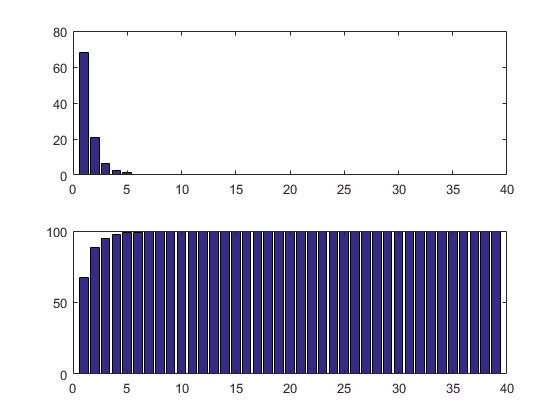

figure
subplot(211)
bar(explainedPM) % Variance explained by each PC

subplot(212)
bar(cumsum(explainedPM)) % Cumulative variace explained by PCs
ylim([0 100])

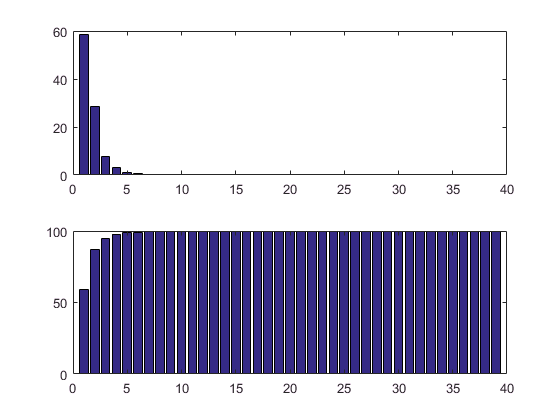


%Same for DL
figure
subplot(211)
bar(explainedDL) % Variance explained by each PC

subplot(212)
bar(cumsum(explainedDL)) % Cumulative variace explained by PCs
ylim([0 100])

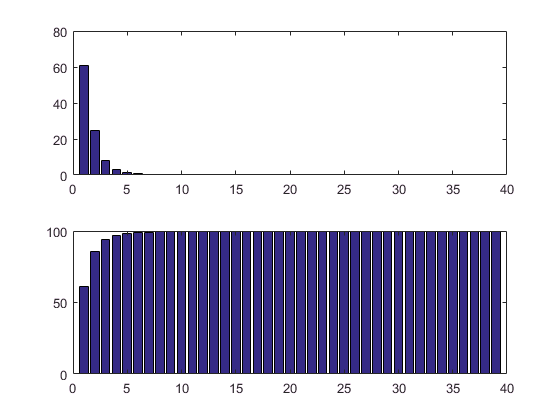


%Both together
figure
subplot(211)
bar(explained) % Variance explained by each PC

subplot(212)
bar(cumsum(explained)) % Cumulative variace explained by PCs
ylim([0 100])

## Fit GLM to kinematics in each workspace and predict neural firing rates (for cross-validation)

% Decompose score from PCA into workspaces
scorePM = scores(1:height(tPM),1:5);
scoreDL = scores(height(tPM)+1:end,1:5);

kinModelPMR2 = zeros(1,width(neurPM));
kinModelDLR2 = zeros(1,width(neurDL));
kinModelAcrossDLR2 = zeros(1,width(neurDL));
kinModelAcrossPMR2 = zeros(1,width(neurDL));
muscleModelPMR2 = zeros(1,width(neurPM));
muscleModelDLR2 = zeros(1,width(neurDL));
muscleModelAcrossDLR2 = zeros(1,width(neurDL));
muscleModelAcrossPMR2 = zeros(1,width(neurDL));

% get training indices and test indices
[trainingIdxPM,testingIdxPM] = crossvalind('LeaveMOut',height(tPM),round(0.2*height(tPM)));
[trainingIdxDL,testingIdxDL] = crossvalind('LeaveMOut',height(tDL),round(0.2*height(tDL)));

% GLM inputs (only use velocities)
kinInputPM = kinPM{trainingIdxPM,3:4};
kinInputDL = kinDL{trainingIdxDL,3:4};
% muscleInputPM = [musclePM{trainingIdxPM,:} muscleVelPM{trainingIdxPM,:}];
% muscleInputDL = [muscleDL{trainingIdxDL,:} muscleVelDL{trainingIdxDL,:}];
muscleInputPM = scorePM(trainingIdxPM,:);
muscleInputDL = scoreDL(trainingIdxDL,:);
kinInputPMtest = kinPM{testingIdxPM,3:4};
kinInputDLtest = kinDL{testingIdxDL,3:4};
% muscleInputPMtest = [musclePM{testingIdxPM,:} muscleVelPM{testingIdxPM,:}];
% muscleInputDLtest = [muscleDL{testingIdxDL,:} muscleVelDL{testingIdxDL,:}];
muscleInputPMtest = scorePM(testingIdxPM,:);
muscleInputDLtest = scoreDL(testingIdxDL,:);

% Get times, just in case
tPMtrain = tPM.t(trainingIdxPM);
tDLtrain = tDL.t(trainingIdxDL);
tPMtest = tPM.t(testingIdxPM);
tDLtest = tDL.t(testingIdxDL);

% initialize neural predictions
kinPredNeurPMfromPM = zeros(sum(testingIdxPM),width(neurPM));
kinPredNeurPMfromDL = zeros(sum(testingIdxPM),width(neurPM));
kinPredNeurDLfromDL = zeros(sum(testingIdxDL),width(neurDL));
kinPredNeurDLfromPM = zeros(sum(testingIdxDL),width(neurDL));

musclePredNeurPMfromPM = zeros(sum(testingIdxPM),width(neurPM));
musclePredNeurPMfromDL = zeros(sum(testingIdxPM),width(neurPM));
musclePredNeurDLfromDL = zeros(sum(testingIdxDL),width(neurDL));
musclePredNeurDLfromPM = zeros(sum(testingIdxDL),width(neurDL));

% initialize weight matrices
for i = 1:width(neurPM)
    % compose GLM outputs
    outputPM = neurPM{trainingIdxPM,i};
    outputDL = neurDL{trainingIdxDL,i};
    outputPMtest = neurPM{testingIdxPM,i};
    outputDLtest = neurDL{testingIdxDL,i};
    
    % fit full GLM on PM and DL
    kinModelPM = fitglm(kinInputPM,outputPM,'Distribution','poisson');
    kinModelDL = fitglm(kinInputDL,outputDL,'Distribution','poisson');
    muscleModelPM = fitglm(muscleInputPM,outputPM,'Distribution','poisson');
    muscleModelDL = fitglm(muscleInputDL,outputDL,'Distribution','poisson');
    
    % Get predicted neural outputs on test data
    kinPredNeurPMfromPM(:,i) = kinModelPM.predict(kinInputPMtest);
    kinPredNeurPMfromDL(:,i) = kinModelDL.predict(kinInputPMtest);
    kinPredNeurDLfromDL(:,i) = kinModelDL.predict(kinInputDLtest);
    kinPredNeurDLfromPM(:,i) = kinModelPM.predict(kinInputDLtest);
    
    musclePredNeurPMfromPM(:,i) = muscleModelPM.predict(muscleInputPMtest);
    musclePredNeurPMfromDL(:,i) = muscleModelDL.predict(muscleInputPMtest);
    musclePredNeurDLfromDL(:,i) = muscleModelDL.predict(muscleInputDLtest);
    musclePredNeurDLfromPM(:,i) = muscleModelPM.predict(muscleInputDLtest);
    
    % compute pseudoR2 on each model
%     kinModelPMR2 = 1-(kinModelPM.LogLikelihood)/(interceptModelPM.LogLikelihood);
%     kinModelDLR2 = 1-(kinModelDL.LogLikelihood)/(interceptModelDL.LogLikelihood);
    kinModelPMR2(i) = compute_pseudo_R2(outputPMtest,kinPredNeurPMfromPM(:,i),mean(outputPMtest));
    kinModelDLR2(i) = compute_pseudo_R2(outputDLtest,kinPredNeurDLfromDL(:,i),mean(outputDLtest));
    muscleModelPMR2(i) = compute_pseudo_R2(outputPMtest,musclePredNeurPMfromPM(:,i),mean(outputPMtest));
    muscleModelDLR2(i) = compute_pseudo_R2(outputDLtest,musclePredNeurDLfromDL(:,i),mean(outputDLtest));
    
    % test across
    kinModelAcrossDLR2(i) = compute_pseudo_R2(outputDLtest,kinPredNeurDLfromPM(:,i),mean(outputDLtest));
    kinModelAcrossPMR2(i) = compute_pseudo_R2(outputPMtest,kinPredNeurPMfromDL(:,i),mean(outputPMtest));
    muscleModelAcrossDLR2(i) = compute_pseudo_R2(outputDLtest,musclePredNeurDLfromPM(:,i),mean(outputDLtest));
    muscleModelAcrossPMR2(i) = compute_pseudo_R2(outputPMtest,musclePredNeurPMfromDL(:,i),mean(outputPMtest));
end


## Look at PM->PM fits

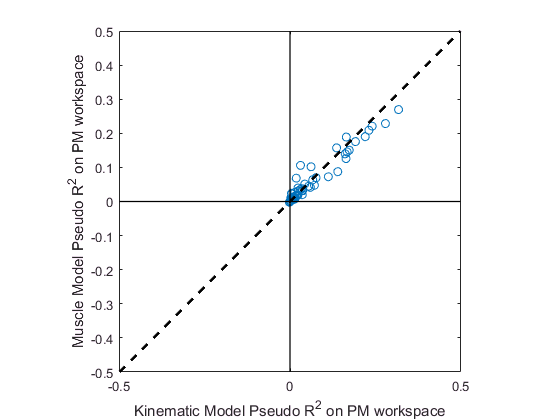

figure
plot(kinModelPMR2,muscleModelPMR2,'o')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',2)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
xlabel('Kinematic Model Pseudo R^2 on PM workspace')
ylabel('Muscle Model Pseudo R^2 on PM workspace')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])

## Look at PM->DL fits

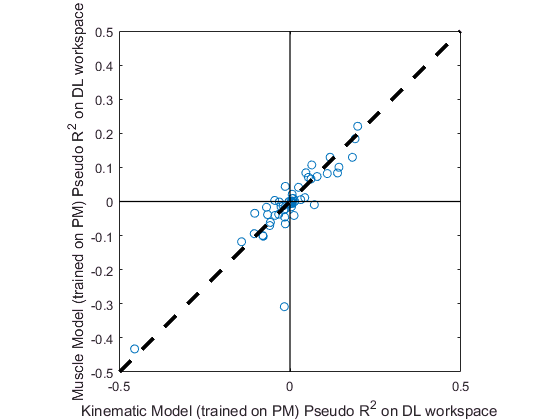

figure
plot(kinModelAcrossDLR2,muscleModelAcrossDLR2,'o')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
xlabel('Kinematic Model (trained on PM) Pseudo R^2 on DL workspace')
ylabel('Muscle Model (trained on PM) Pseudo R^2 on DL workspace')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])

## Try fitting over both workspaces and predicting individual workspaces

This didn't do any better than the earlier fits above...

% kinInput = [kinInputPM;kinInputDL];
% muscleInput = [muscleInputPM;muscleInputDL];
% for i = 1:width(neurPM)
%     % compose GLM outputs
%     output = [neurPM{trainingIdxPM,i};neurDL{trainingIdxDL,i}];
%     outputPMtest = neurPM{testingIdxPM,i};
%     outputDLtest = neurDL{testingIdxDL,i};
%     
%     % fit full GLM on PM and DL
%     kinModel = fitglm(kinInput,output,'Distribution','poisson');
%     muscleModel = fitglm(muscleInput,output,'Distribution','poisson');
%     
%     % compute pseudoR2 on each model
%     kinModelPMR2(i) = compute_pseudo_R2(outputPMtest,kinModel.predict(kinInputPMtest),mean(outputPMtest));
%     kinModelDLR2(i) = compute_pseudo_R2(outputDLtest,kinModel.predict(kinInputDLtest),mean(outputDLtest));
%     muscleModelPMR2(i) = compute_pseudo_R2(outputPMtest,muscleModel.predict(muscleInputPMtest),mean(outputPMtest));
%     muscleModelDLR2(i) = compute_pseudo_R2(outputDLtest,muscleModel.predict(muscleInputDLtest),mean(outputDLtest));
% end


## Predict tuning curves

% First get all tuning curves we want
[curvesPM,bins] = getTuningCurves(kinInputPMtest,neurPM{testingIdxPM,:});
[curvesDL,~] = getTuningCurves(kinInputDLtest,neurDL{testingIdxDL,:});

[kinPredCurvesPMfromPM,~] = getTuningCurves(kinInputPMtest,kinPredNeurPMfromPM);
[kinPredCurvesDLfromDL,~] = getTuningCurves(kinInputDLtest,kinPredNeurDLfromDL);
[kinPredCurvesPMfromDL,~] = getTuningCurves(kinInputPMtest,kinPredNeurPMfromDL);
[kinPredCurvesDLfromPM,~] = getTuningCurves(kinInputDLtest,kinPredNeurDLfromPM);

[musclePredCurvesPMfromPM,~] = getTuningCurves(kinInputPMtest,musclePredNeurPMfromPM);
[musclePredCurvesDLfromDL,~] = getTuningCurves(kinInputDLtest,musclePredNeurDLfromDL);
[musclePredCurvesPMfromDL,~] = getTuningCurves(kinInputPMtest,musclePredNeurPMfromDL);
[musclePredCurvesDLfromPM,~] = getTuningCurves(kinInputDLtest,musclePredNeurDLfromPM);


## Get predicted preferred directions

weightsPM = zeros(width(neurPM),2);
weightsDL = zeros(width(neurDL),2);

kinPredWeightsPMfromPM = zeros(width(neurPM),2);
kinPredWeightsDLfromDL = zeros(width(neurDL),2);
kinPredWeightsPMfromDL = zeros(width(neurPM),2);
kinPredWeightsDLfromPM = zeros(width(neurDL),2);

musclePredWeightsPMfromPM = zeros(width(neurPM),2);
musclePredWeightsDLfromDL = zeros(width(neurDL),2);
musclePredWeightsPMfromDL = zeros(width(neurPM),2);
musclePredWeightsDLfromPM = zeros(width(neurDL),2);
for i = 1:width(neurPM)
    % compose GLM outputs
    outputPMtest = neurPM{testingIdxPM,i};
    outputDLtest = neurDL{testingIdxDL,i};
    
    kinModelPM = fitglm(kinInputPMtest,outputPMtest,'Distribution','poisson');
    kinModelDL = fitglm(kinInputDLtest,outputDLtest,'Distribution','poisson');
    
    kinModelPMfromPM = fitglm(kinInputPMtest,kinPredNeurPMfromPM(:,i),'Distribution','poisson');
    kinModelDLfromDL = fitglm(kinInputDLtest,kinPredNeurDLfromDL(:,i),'Distribution','poisson');
    kinModelPMfromDL = fitglm(kinInputPMtest,kinPredNeurPMfromDL(:,i),'Distribution','poisson');
    kinModelDLfromPM = fitglm(kinInputDLtest,kinPredNeurDLfromPM(:,i),'Distribution','poisson');
    
    muscleModelPMfromPM = fitglm(kinInputPMtest,musclePredNeurPMfromPM(:,i),'Distribution','poisson');
    muscleModelDLfromDL = fitglm(kinInputDLtest,musclePredNeurDLfromDL(:,i),'Distribution','poisson');
    muscleModelPMfromDL = fitglm(kinInputPMtest,musclePredNeurPMfromDL(:,i),'Distribution','poisson');
    muscleModelDLfromPM = fitglm(kinInputDLtest,musclePredNeurDLfromPM(:,i),'Distribution','poisson');
    
    weightsPM(i,:) = kinModelPM.Coefficients.Estimate(2:3)';
    weightsDL(i,:) = kinModelDL.Coefficients.Estimate(2:3)';
    
    kinPredWeightsPMfromPM(i,:) = kinModelPMfromPM.Coefficients.Estimate(2:3)';
    kinPredWeightsDLfromDL(i,:) = kinModelDLfromDL.Coefficients.Estimate(2:3)';
    kinPredWeightsPMfromDL(i,:) = kinModelPMfromDL.Coefficients.Estimate(2:3)';
    kinPredWeightsDLfromPM(i,:) = kinModelDLfromPM.Coefficients.Estimate(2:3)';
    
    musclePredWeightsPMfromPM(i,:) = muscleModelPMfromPM.Coefficients.Estimate(2:3)';
    musclePredWeightsDLfromDL(i,:) = muscleModelDLfromDL.Coefficients.Estimate(2:3)';
    musclePredWeightsPMfromDL(i,:) = muscleModelPMfromDL.Coefficients.Estimate(2:3)';
    musclePredWeightsDLfromPM(i,:) = muscleModelDLfromPM.Coefficients.Estimate(2:3)';
end
    


## Predict tuning curves within workspace using kin and muscle models

Find that muscle model seems to match the kinematic model tuning curves fairly well. Both predict the actual tuning curves decently.

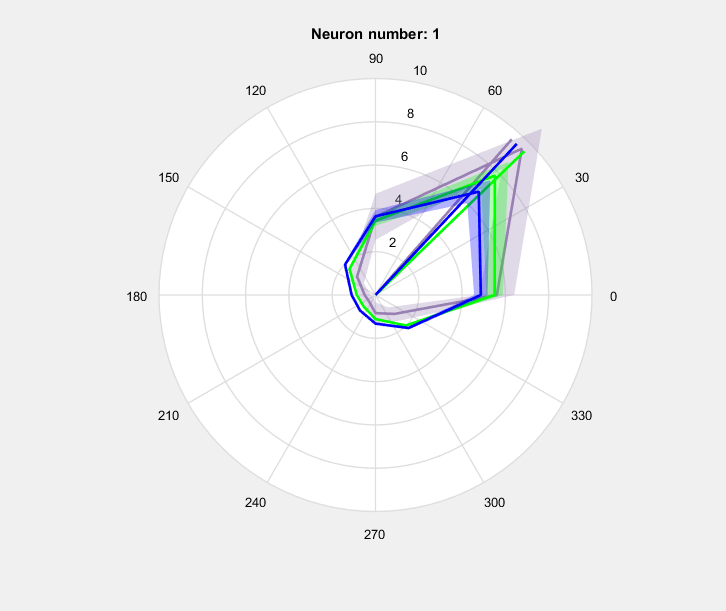

colorPM = [0.6 0.5 0.7];
colorDL = [1 0 0];
colorPredKin =  [0 1 0];
colorPredMuscle = [0 0 1];

figure

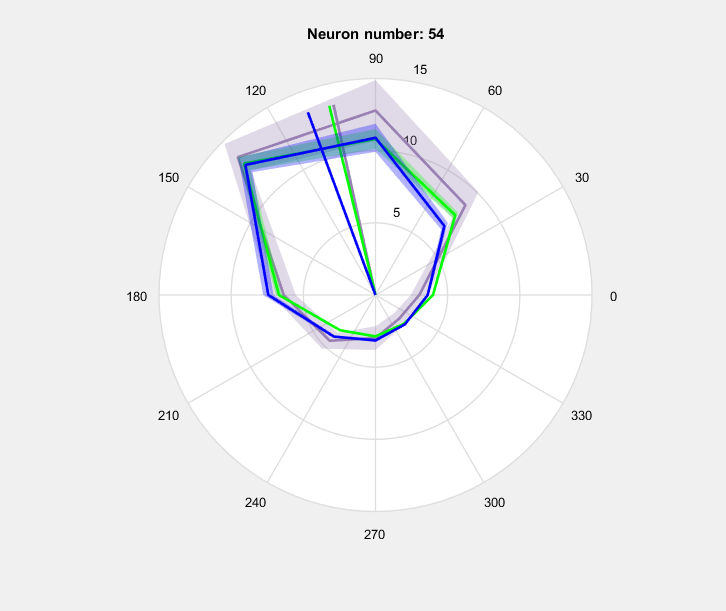

for i = 1:height(curvesPM)
    clf
    maxRad = max([curvesPM.binnedFR(i,:) kinPredCurvesPMfromPM.binnedFR(i,:) musclePredCurvesPMfromPM.binnedFR(i,:)]);
    
    plotTuning(bins,weightsPM(i,:),curvesPM(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,kinPredWeightsPMfromPM(i,:),kinPredCurvesPMfromPM(i,:),maxRad,colorPredKin)
    plotTuning(bins,musclePredWeightsPMfromPM(i,:),musclePredCurvesPMfromPM(i,:),maxRad,colorPredMuscle)
    title(['Neuron number: ' num2str(i)])
    waitforbuttonpress
end

## Same for DL

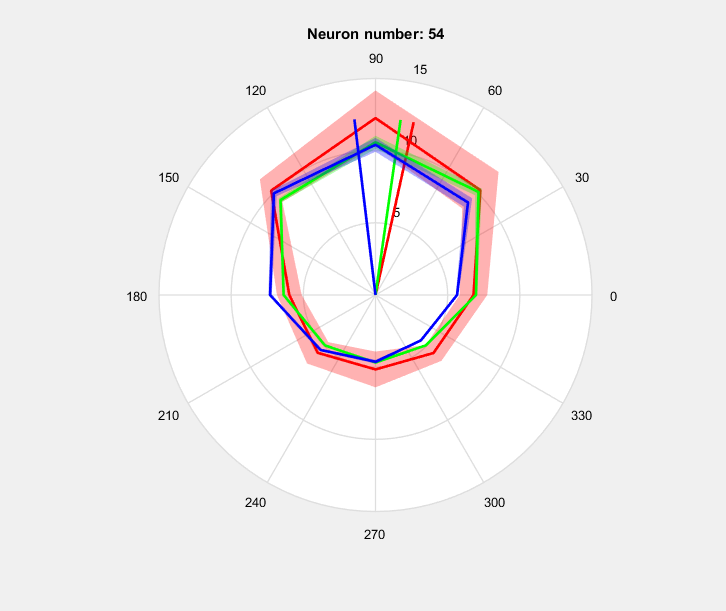

for i = 1:height(curvesDL)
    clf
    maxRad = max([curvesDL.binnedFR(i,:) kinPredCurvesDLfromDL.binnedFR(i,:) musclePredCurvesDLfromDL.binnedFR(i,:)]);
    
    plotTuning(bins,weightsDL(i,:),curvesDL(i,:),maxRad,colorDL)
    hold on
    plotTuning(bins,kinPredWeightsDLfromDL(i,:),kinPredCurvesDLfromDL(i,:),maxRad,colorPredKin)
    plotTuning(bins,musclePredWeightsDLfromDL(i,:),musclePredCurvesDLfromDL(i,:),maxRad,colorPredMuscle)
    title(['Neuron number: ' num2str(i)])
    waitforbuttonpress
end

## Try predicting opposite workspace tuning curves

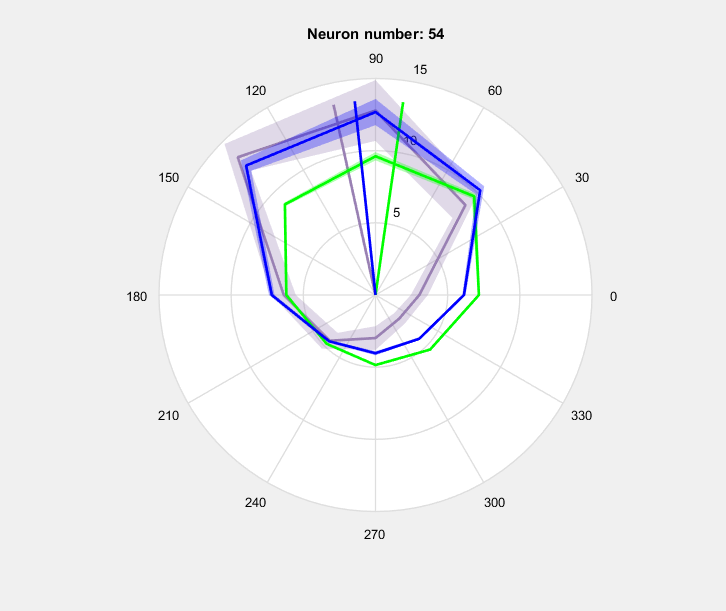

for i = 1:height(curvesPM)
    clf
    maxRad = max([curvesPM.binnedFR(i,:) kinPredCurvesPMfromDL.binnedFR(i,:) musclePredCurvesPMfromDL.binnedFR(i,:)]);
    
    plotTuning(bins,weightsPM(i,:),curvesPM(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,kinPredWeightsPMfromDL(i,:),kinPredCurvesPMfromDL(i,:),maxRad,colorPredKin)
    plotTuning(bins,musclePredWeightsPMfromDL(i,:),musclePredCurvesPMfromDL(i,:),maxRad,colorPredMuscle)
    title(['Neuron number: ' num2str(i)])
    waitforbuttonpress
end

## Same for DL (opposite)

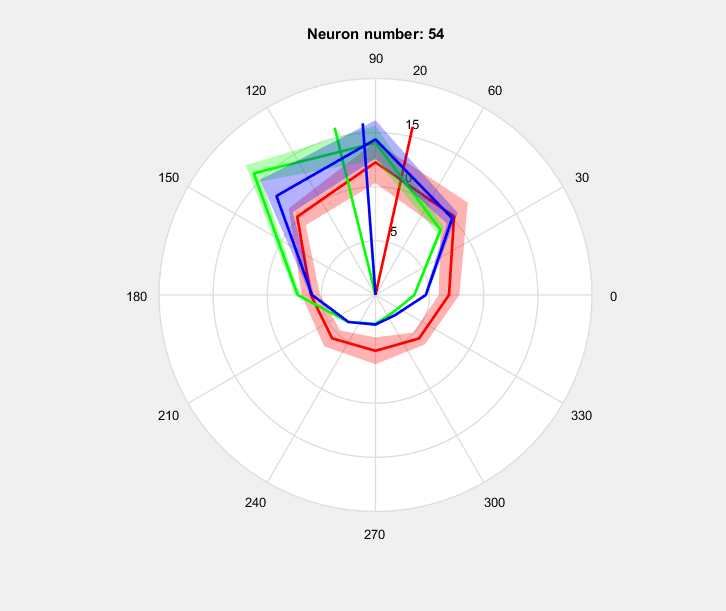

for i = 1:height(curvesDL)
    clf
    maxRad = max([curvesDL.binnedFR(i,:) kinPredCurvesDLfromPM.binnedFR(i,:) musclePredCurvesDLfromPM.binnedFR(i,:)]);
    
    plotTuning(bins,weightsDL(i,:),curvesDL(i,:),maxRad,colorDL)
    hold on
    plotTuning(bins,kinPredWeightsDLfromPM(i,:),kinPredCurvesDLfromPM(i,:),maxRad,colorPredKin)
    plotTuning(bins,musclePredWeightsDLfromPM(i,:),musclePredCurvesDLfromPM(i,:),maxRad,colorPredMuscle)
    title(['Neuron number: ' num2str(i)])
    waitforbuttonpress
end